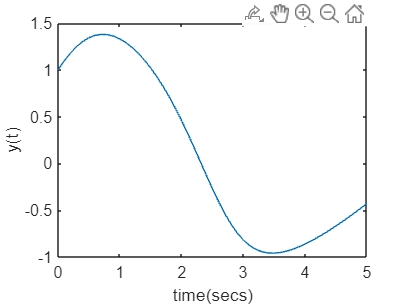

syms y v;

F = [v;(y*(1-y)*v)-y];
Y = [y;v];

h = 0.1;
init_t = 0;
final_t = 5;
time = init_t:h:final_t;

q_init = [1;1];
q_iters = zeros([2 size(time,2)]);
q_iters(:,1) = q_init;

i = 1;
K1 = zeros(2,1);
K2 = zeros(2,1);
K3 = zeros(2,1);
K4 = zeros(2,1);
K = zeros(2,1);
y_iter = zeros(2,1);

digits(10);
for t = init_t:h:final_t-h
    y_iter = (double(subs(Y,[y,v],transpose(q_iters(:,i)))));
    K1 = h*((double(subs(F,[y,v],transpose(y_iter)))));
    K2 = h*((double(subs(F,[y,v],transpose(y_iter + (K1/2))))));
    K3 = h*((double(subs(F,[y,v],transpose(y_iter + (K2/2))))));
    K4 = h*((double(subs(F,[y,v],transpose(y_iter + (K3))))));
    K = (K1 + (2*K2) + (2*K3) + (K4))/6;
    q_iters(:,i+1) = q_iters(:,i) + K;
    i = i+1;
end

plot((time),q_iters(1,:));

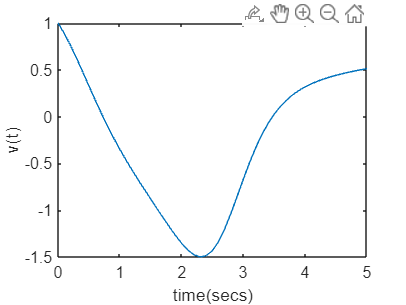

plot((time),q_iters(2,:));